# Machine Learning Online Class - Exercise 2: Logistic Regression

`Instructions`

`------------`

`This file contains code that helps you get started on the logistic`

`regression exercise. You will need to complete the following functions `

`in this exericse:`

`   sigmoid.m`

`   costFunction.m`

`   predict.m`

`   costFunctionReg.m`

`For this exercise, you will not need to change any code in this file,`

`or any other files other than those mentioned above.`

## Initialization

clear ; close all; clc

## Load Data

`The first two columns contains the exam scores and the third column`

`contains the label.`

data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

## ==================== Part 1: Plotting ====================

`We start the exercise by first plotting the data to understand the `

`the problem we are working with.`

fprintf(['Plotting data with + indicating (y = 1) examples and o ' ...
         'indicating (y = 0) examples.\n']);

Plotting data with + indicating (y = 1) examples and o indicating (y = 0) examples.


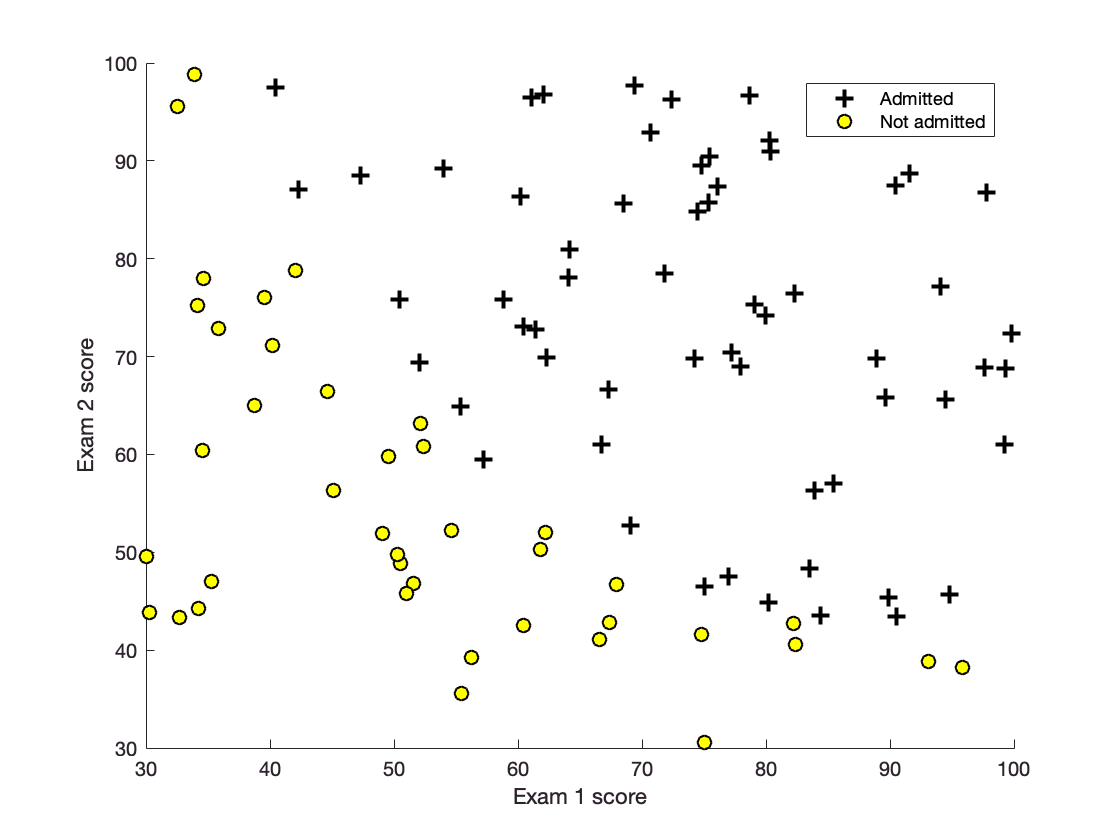


plotData(X, y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')


% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


%pause;

## ============ Part 2: Compute Cost and Gradient ============

`In this part of the exercise, you will implement the cost and gradient`

`for logistic regression. You neeed to complete the code in `

`costFunction.m`

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);

fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.006931


fprintf('Expected cost (approx): 0.693\n');

Expected cost (approx): 0.693


fprintf('Gradient at initial theta (zeros): \n');

Gradient at initial theta (zeros): 


fprintf(' %f \n', grad);

 -0.300000 
 -36.027650 
 -33.788527 


fprintf('Expected gradients (approx):\n -0.1000\n -12.0092\n -11.2628\n');

Expected gradients (approx):
 -0.1000
 -12.0092
 -11.2628



% Compute and display cost and gradient with non-zero theta
test_theta = [-24; 0.2; 0.2];
[cost, grad] = costFunction(test_theta, X, y);

fprintf('\nCost at test theta: %f\n', cost);


Cost at test theta: 0.000001


fprintf('Expected cost (approx): 0.218\n');

Expected cost (approx): 0.218


fprintf('Gradient at test theta: \n');

Gradient at test theta: 


fprintf(' %f \n', grad);

 0.128709 
 7.698702 
 7.940392 


fprintf('Expected gradients (approx):\n 0.043\n 2.566\n 2.647\n');

Expected gradients (approx):
 0.043
 2.566
 2.647



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


%pause;

## ============= Part 3: Optimizing using fminunc =============

`In this exercise, you will use a built-in function (fminunc) to find the`

`optimal parameters theta.`

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = ...
	fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>




% Print theta to screen
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.000751


fprintf('Expected cost (approx): 0.203\n');

Expected cost (approx): 0.203


fprintf('theta: \n');

theta: 


fprintf(' %f \n', theta);

 -5.636220 
 0.035492 
 0.061808 


fprintf('Expected theta (approx):\n');

Expected theta (approx):


fprintf(' -25.161\n 0.206\n 0.201\n');

 -25.161
 0.206
 0.201



% Plot Boundary
plotDecisionBoundary(theta, X, y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============== Part 4: Predict and Accuracies ==============

`After learning the parameters, you'll like to use it to predict the outcomes`

`on unseen data. In this part, you will use the logistic regression model`

`to predict the probability that a student with score 45 on exam 1 and `

`score 85 on exam 2 will be admitted.`

`Furthermore, you will compute the training and test set accuracies of `

`our model.`

`Your task is to complete the code in predict.m`

%  Predict probability for a student with score 45 on exam 1 
%  and score 85 on exam 2 

prob = sigmoid([1 45 85] * theta);
fprintf(['For a student with scores 45 and 85, we predict an admission ' ...
         'probability of %f\n'], prob);
fprintf('Expected value: 0.775 +/- 0.002\n\n');

% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);
fprintf('Expected accuracy (approx): 89.0\n');
fprintf('\n');